# Lab Template

This is an mlx (matlab live script) template for the labs. Live Script allows you to mix code with text. Try to structure you code with one cell/section per exercise and keep all functions in the ./functions directory and all images in the ./images directory.

## Setting up environment

Here we clear old variables and make sure that ./functions and ./images are in the path.

% use clear to avoid unknowingly being dependent on 
% variables in the workspace defined by other scripts
% or in the command window
clear;

%add ./functions and ./images folders to path
%addpath('./functions');
%addpath('./images');


## Load dataset

trainImagesFile = 'train-images.idx3-ubyte';
testImagesFile = 't10k-images.idx3-ubyte';
testLabelsFile = 't10k-labels.idx1-ubyte';

XTrain = processMNISTimages(trainImagesFile);


Read MNIST image data...
Number of images in the dataset:  60000 ...



XTest = processMNISTimages(testImagesFile);


Read MNIST image data...
Number of images in the dataset:  10000 ...



YTest = processMNISTlabels(testLabelsFile);


Read MNIST label data...
Number of labels in the dataset:  10000 ...


## Test 0, baseline

fprintf("Test 0 \n")

Test 0 


[encoderNet,decoderNet, latentDim, numEpochs, lr, momentum] = get_baseline_param();

[encoderNet0, decoderNet0] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, XTrain, XTest);

Epoch : 1 Test ELBO loss = 27.7283. Time taken for epoch = 114.7829s 
Epoch : 2 Test ELBO loss = 26.2369. Time taken for epoch = 114.9376s 
Epoch : 3 Test ELBO loss = 25.6523. Time taken for epoch = 111.3457s 
Epoch : 4 Test ELBO loss = 25.2147. Time taken for epoch = 111.2388s 
Epoch : 5 Test ELBO loss = 24.6992. Time taken for epoch = 111.3571s 
Epoch : 6 Test ELBO loss = 24.2922. Time taken for epoch = 110.4842s 
Epoch : 7 Test ELBO loss = 23.9042. Time taken for epoch = 110.3554s 
Epoch : 8 Test ELBO loss = 23.6729. Time taken for epoch = 110.3973s 
Epoch : 9 Test ELBO loss = 23.4582. Time taken for epoch = 112.1098s 
Epoch : 10 Test ELBO loss = 23.3382. Time taken for epoch = 105.7752s 
Epoch : 11 Test ELBO loss = 23.1487. Time taken for epoch = 94.2497s 
Epoch : 12 Test ELBO loss = 23.0763. Time taken for epoch = 94.0714s 
Epoch : 13 Test ELBO loss = 22.9706. Time taken for epoch = 94.4532s 
Epoch : 14 Test ELBO loss = 22.8544. Time taken for epoch = 94.2006s 
Epoch : 15 Test ELB

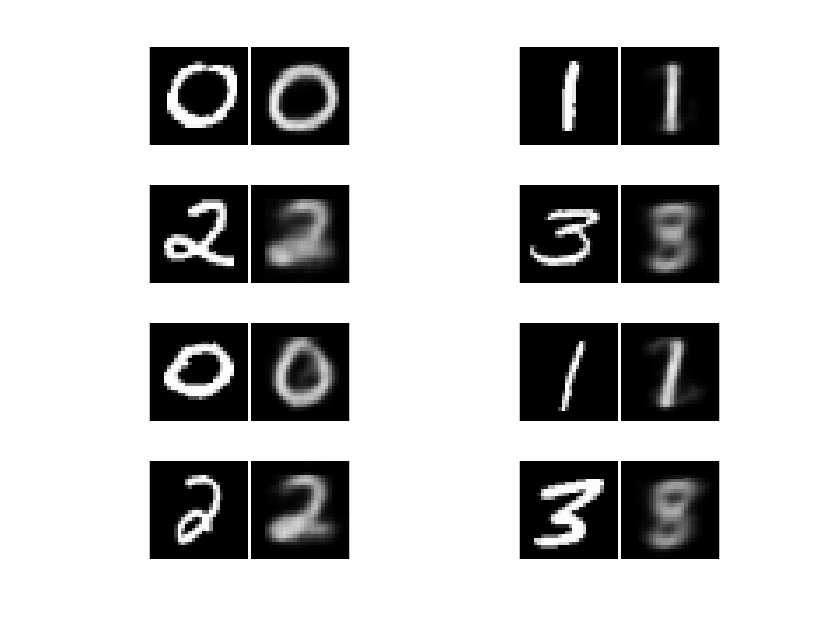


visualizeReconstruction(XTest, YTest, encoderNet0, decoderNet0)

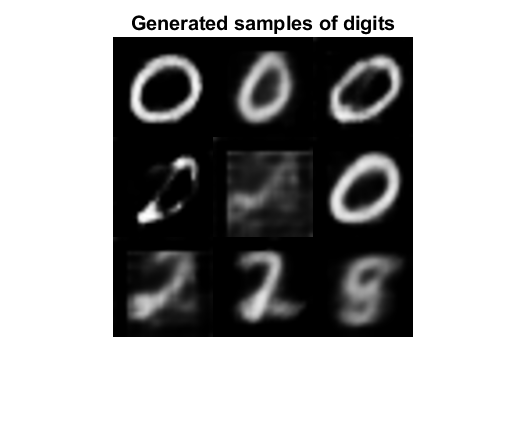

%visualizeLatentSpace(XTest, YTest, encoderNet)
generate(decoderNet0, latentDim)

## Test 1

fprintf("Test 1 \n")

Test 1 


latentDim = 2;
imageSize = [28 28 1];
numEpochs = 20;
lr = 1e-3;
momentum = 1;

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

[encoderNet1, decoderNet1] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, XTrain, XTest);

Epoch : 1 Test ELBO loss = 27.7813. Time taken for epoch = 96.0948s 
Epoch : 2 Test ELBO loss = 26.3673. Time taken for epoch = 96.6249s 
Epoch : 3 Test ELBO loss = 25.8546. Time taken for epoch = 95.9819s 
Epoch : 4 Test ELBO loss = 25.2101. Time taken for epoch = 96.0167s 
Epoch : 5 Test ELBO loss = 24.5009. Time taken for epoch = 96.1546s 
Epoch : 6 Test ELBO loss = 24.1581. Time taken for epoch = 96.5782s 
Epoch : 7 Test ELBO loss = 23.8376. Time taken for epoch = 90.3922s 
Epoch : 8 Test ELBO loss = 23.7419. Time taken for epoch = 86.9845s 
Epoch : 9 Test ELBO loss = 23.4864. Time taken for epoch = 87.0554s 
Epoch : 10 Test ELBO loss = 23.3855. Time taken for epoch = 87.0165s 
Epoch : 11 Test ELBO loss = 23.263. Time taken for epoch = 87.4857s 
Epoch : 12 Test ELBO loss = 23.2017. Time taken for epoch = 87.4559s 
Epoch : 13 Test ELBO loss = 23.1313. Time taken for epoch = 88.3163s 
Epoch : 14 Test ELBO loss = 22.9552. Time taken for epoch = 87.5319s 
Epoch : 15 Test ELBO loss = 22

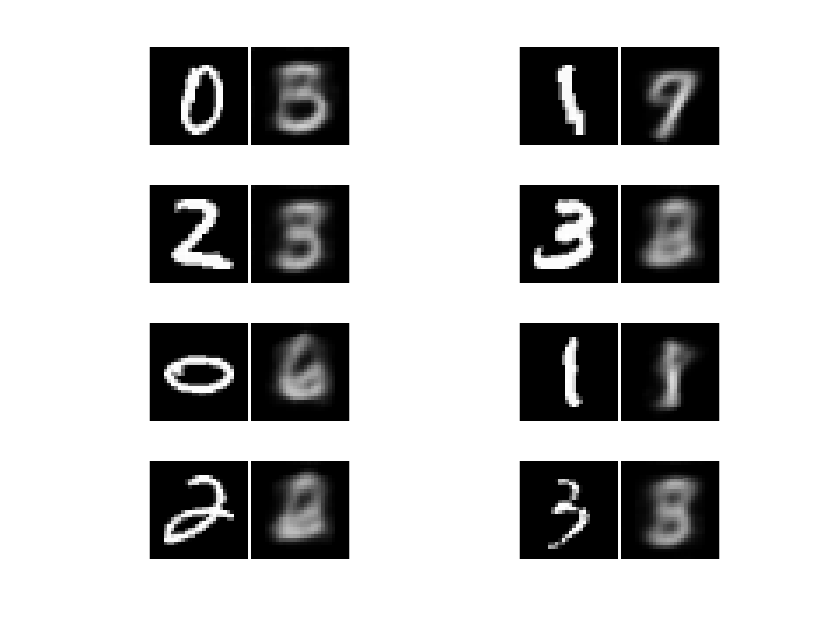


visualizeReconstruction(XTest, YTest, encoderNet1, decoderNet1)

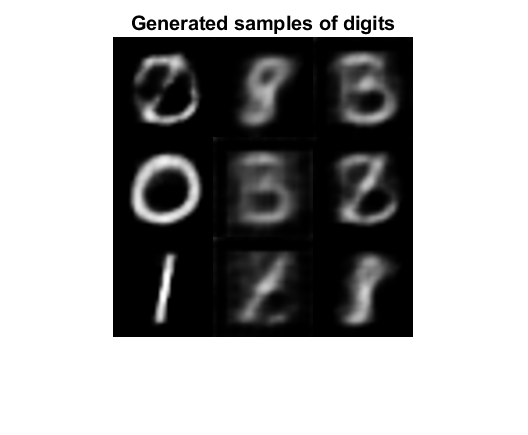

generate(decoderNet1, latentDim)

## Test 2

fprintf("Test 2 \n")

Test 2 


latentDim = 20;
imageSize = [28 28 1];
numEpochs = 2;
lr = 1e-3;
momentum = 1;

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv3')
    reluLayer('Name','relu3')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(3, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

[encoderNet2, decoderNet2] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, XTrain, XTest);

Epoch : 1 Test ELBO loss = 27.0812. Time taken for epoch = 107.2436s 
Epoch : 2 Test ELBO loss = 25.079. Time taken for epoch = 107.3733s 


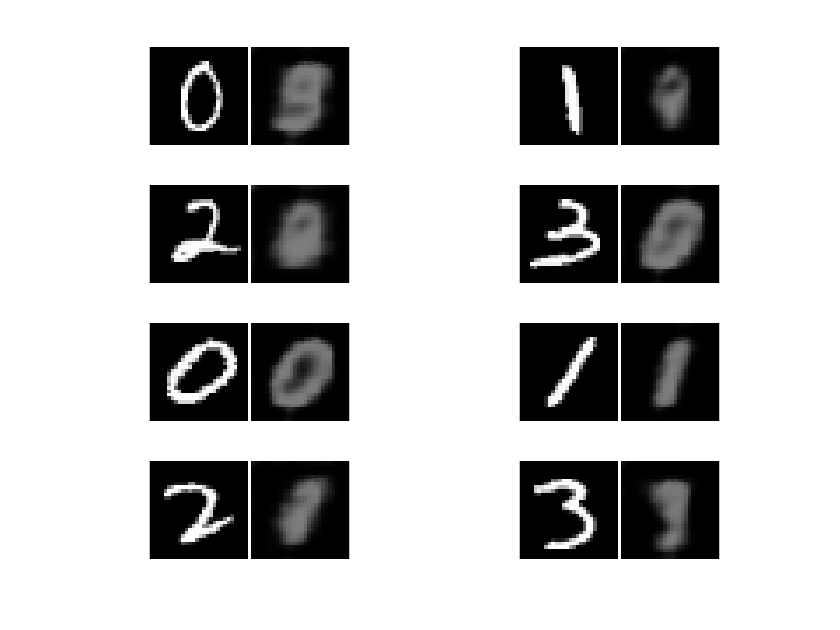

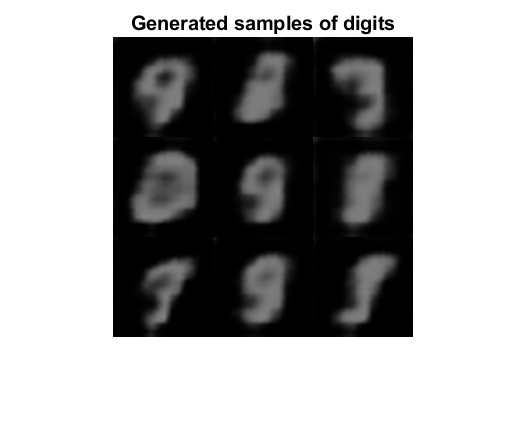


visualizeReconstruction(XTest, YTest, encoderNet2, decoderNet2)
generate(decoderNet2, latentDim)

## Test 3

%{
fprintf("Test 3 \n")
latentDim = 2;
imageSize = [28 28 1];
numEpochs = 20;
lr = 1e-3;
momentum = 1;

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(1, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

[encoderNet3, decoderNet3] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, XTrain, XTest);

visualizeReconstruction(XTest, YTest, encoderNet3, decoderNet3)
generate(decoderNet3, latentDim)
%}

## Test 4

%{
fprintf("Test 4 \n")
latentDim = 2;
imageSize = [28 28 1];
numEpochs = 20;
lr = 1e-3;
momentum = 1;

encoderLG = layerGraph([
    imageInputLayer(imageSize,'Name','input_encoder','Normalization','none')
    convolution2dLayer(3, 32, 'Padding','same', 'Stride', 2, 'Name', 'conv1')
    reluLayer('Name','relu1')
    convolution2dLayer(3, 64, 'Padding','same', 'Stride', 2, 'Name', 'conv2')
    reluLayer('Name','relu2')
    fullyConnectedLayer(2 * latentDim, 'Name', 'fc_encoder')
    ]);

decoderLG = layerGraph([
    imageInputLayer([1 1 latentDim],'Name','i','Normalization','none')
    transposedConv2dLayer(7, 64, 'Cropping', 'same', 'Stride', 7, 'Name', 'transpose1')
    reluLayer('Name','relu1')
    transposedConv2dLayer(100, 64, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose2')
    reluLayer('Name','relu2')
    transposedConv2dLayer(3, 32, 'Cropping', 'same', 'Stride', 2, 'Name', 'transpose3')
    reluLayer('Name','relu3')
    transposedConv2dLayer(3, 1, 'Cropping', 'same', 'Name', 'transpose4')
    ]);

encoderNet = dlnetwork(encoderLG);
decoderNet = dlnetwork(decoderLG);

[encoderNet4, decoderNet4] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, XTrain, XTest);

visualizeReconstruction(XTest, YTest, encoderNet4, decoderNet4)
generate(decoderNet4, latentDim)
%}

## Test 5

fprintf("Test 5 \n")

Test 5 


[encoderNet,decoderNet, latentDim, ~, lr, momentum] = get_baseline_param();

numEpochs = 5

numEpochs = 5


[encoderNet5, decoderNet5] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, XTrain, XTest);

Epoch : 1 Test ELBO loss = 28.2998. Time taken for epoch = 102.7391s 
Epoch : 2 Test ELBO loss = 26.536. Time taken for epoch = 103.1021s 
Epoch : 3 Test ELBO loss = 25.8647. Time taken for epoch = 113.583s 
Epoch : 4 Test ELBO loss = 25.2164. Time taken for epoch = 102.6696s 
Epoch : 5 Test ELBO loss = 24.5137. Time taken for epoch = 103.1103s 


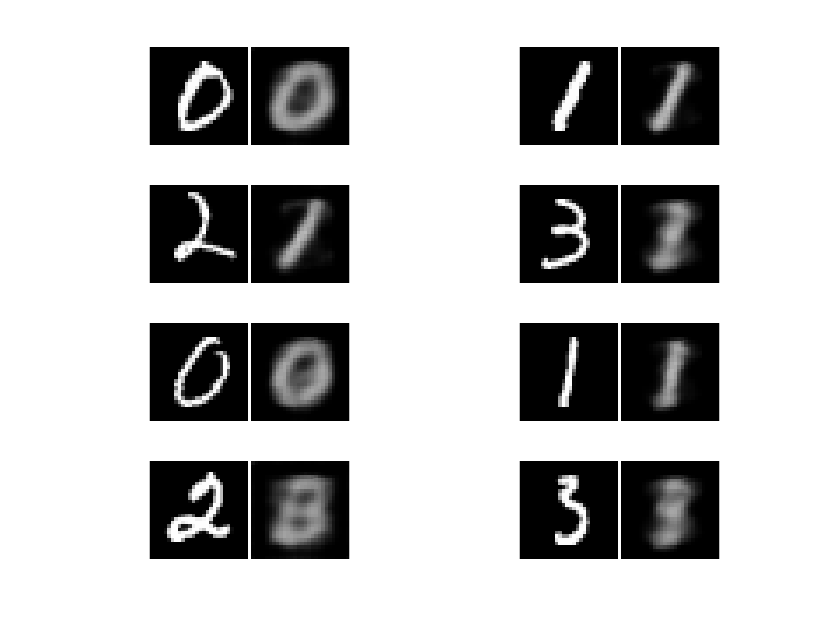

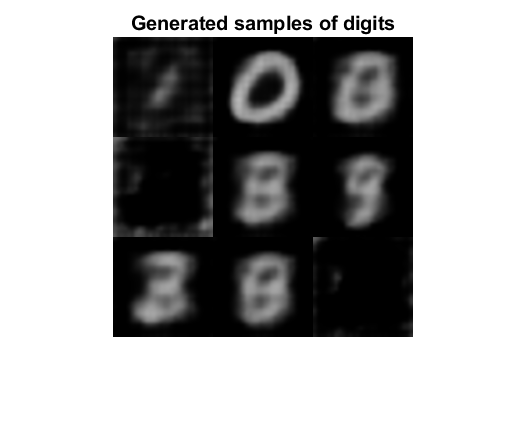


visualizeReconstruction(XTest, YTest, encoderNet5, decoderNet5)
generate(decoderNet5, latentDim)

## Test 6

fprintf("Test 6 \n")

Test 6 


[encoderNet,decoderNet, latentDim, ~, lr, momentum] = get_baseline_param();

numEpochs = 50

numEpochs = 50


[encoderNet6, decoderNet6] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, XTrain, XTest);

Epoch : 1 Test ELBO loss = 27.933. Time taken for epoch = 102.6392s 
Epoch : 2 Test ELBO loss = 26.2862. Time taken for epoch = 102.6609s 
Epoch : 3 Test ELBO loss = 25.633. Time taken for epoch = 102.5808s 
Epoch : 4 Test ELBO loss = 24.823. Time taken for epoch = 102.6556s 
Epoch : 5 Test ELBO loss = 24.4266. Time taken for epoch = 102.7275s 
Epoch : 6 Test ELBO loss = 24.1729. Time taken for epoch = 99.391s 
Epoch : 7 Test ELBO loss = 23.8894. Time taken for epoch = 92.9347s 
Epoch : 8 Test ELBO loss = 23.75. Time taken for epoch = 92.9406s 
Epoch : 9 Test ELBO loss = 23.5408. Time taken for epoch = 92.8303s 
Epoch : 10 Test ELBO loss = 23.3427. Time taken for epoch = 92.8566s 
Epoch : 11 Test ELBO loss = 23.3278. Time taken for epoch = 93.0484s 
Epoch : 12 Test ELBO loss = 23.1393. Time taken for epoch = 92.8511s 
Epoch : 13 Test ELBO loss = 22.9717. Time taken for epoch = 92.945s 
Epoch : 14 Test ELBO loss = 22.921. Time taken for epoch = 93.0139s 
Epoch : 15 Test ELBO loss = 22.7

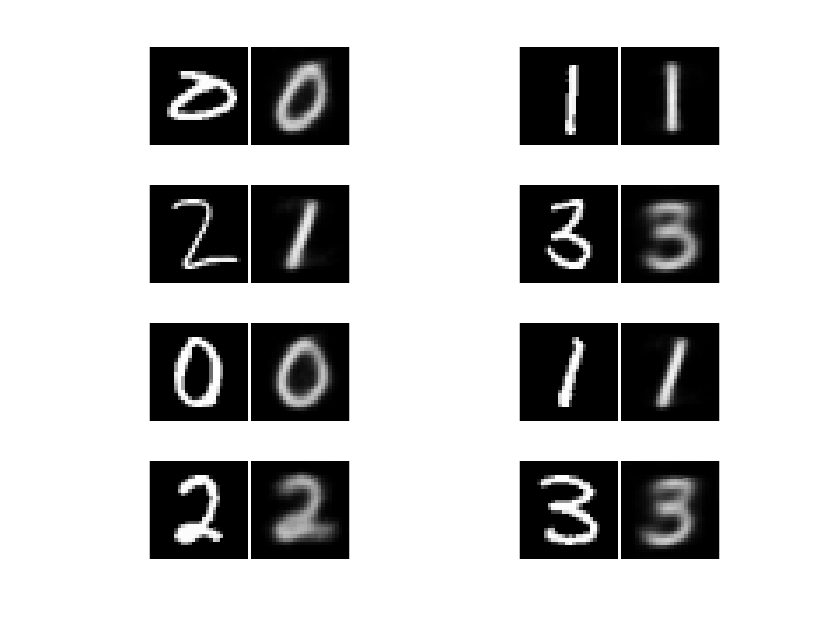

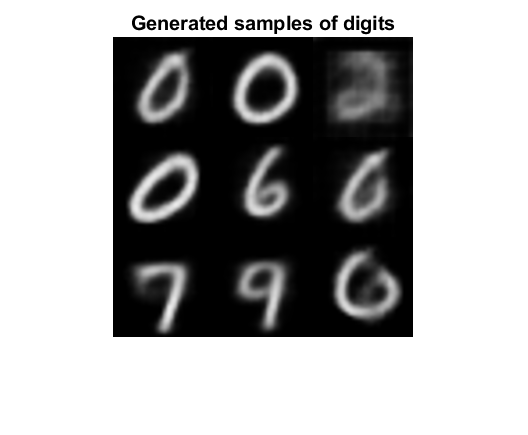


visualizeReconstruction(XTest, YTest, encoderNet6, decoderNet6)
generate(decoderNet6, latentDim)

## Test 7

fprintf("Test 7 \n")

Test 7 


[encoderNet,decoderNet, latentDim, numEpochs, ~, momentum] = get_baseline_param();

lr = 1e-2;

[encoderNet7, decoderNet7] = run_training(numEpochs, lr, momentum, encoderNet,decoderNet, XTrain, XTest);

Epoch : 1 Test ELBO loss = 27.4109. Time taken for epoch = 93.2451s 
Epoch : 2 Test ELBO loss = 26.7982. Time taken for epoch = 92.6863s 
Epoch : 3 Test ELBO loss = 26.6028. Time taken for epoch = 92.6406s 
Epoch : 4 Test ELBO loss = 26.5612. Time taken for epoch = 92.6072s 
Epoch : 5 Test ELBO loss = 26.5317. Time taken for epoch = 92.8411s 
Epoch : 6 Test ELBO loss = 26.537. Time taken for epoch = 93.8341s 
Epoch : 7 Test ELBO loss = 26.5184. Time taken for epoch = 92.7735s 
Epoch : 8 Test ELBO loss = 26.5059. Time taken for epoch = 92.5763s 
Epoch : 9 Test ELBO loss = 26.5255. Time taken for epoch = 92.6311s 
Epoch : 10 Test ELBO loss = 26.5324. Time taken for epoch = 92.6753s 
Epoch : 11 Test ELBO loss = 26.5342. Time taken for epoch = 92.6093s 
Epoch : 12 Test ELBO loss = 26.5898. Time taken for epoch = 92.684s 
Epoch : 13 Test ELBO loss = 26.6101. Time taken for epoch = 92.7627s 
Epoch : 14 Test ELBO loss = 26.6023. Time taken for epoch = 92.7204s 
Epoch : 15 Test ELBO loss = 26.

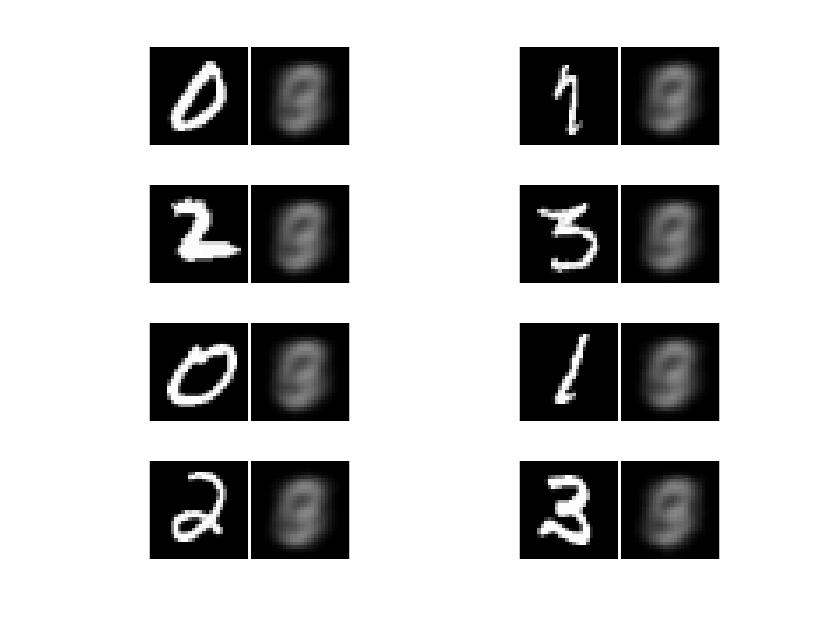


visualizeReconstruction(XTest, YTest, encoderNet7, decoderNet7)

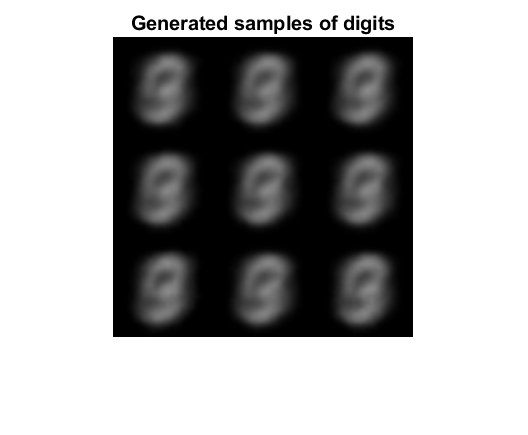

generate(decoderNet7, latentDim)

## Test 8

fprintf("Test 8 \n")

Test 8 


[encoderNet,decoderNet, latentDim, numEpochs, ~, momentum] = get_baseline_param();

lr = 1e-4;

[encoderNet8, decoderNet8] = run_training(numEpochs, lr, momentum, encoderNet, decoderNet, XTrain, XTest);

Epoch : 1 Test ELBO loss = 51.3441. Time taken for epoch = 92.9516s 
Epoch : 2 Test ELBO loss = 34.9074. Time taken for epoch = 92.7661s 
Epoch : 3 Test ELBO loss = 30.3457. Time taken for epoch = 92.7923s 
Epoch : 4 Test ELBO loss = 29.1784. Time taken for epoch = 92.9074s 
Epoch : 5 Test ELBO loss = 28.4126. Time taken for epoch = 92.7941s 
Epoch : 6 Test ELBO loss = 27.7301. Time taken for epoch = 92.8476s 
Epoch : 7 Test ELBO loss = 27.2239. Time taken for epoch = 92.9731s 
Epoch : 8 Test ELBO loss = 26.8975. Time taken for epoch = 92.8575s 
Epoch : 9 Test ELBO loss = 26.6503. Time taken for epoch = 92.8716s 
Epoch : 10 Test ELBO loss = 26.4449. Time taken for epoch = 93.0349s 
Epoch : 11 Test ELBO loss = 26.2724. Time taken for epoch = 92.8862s 
Epoch : 12 Test ELBO loss = 26.1188. Time taken for epoch = 93.0489s 
Epoch : 13 Test ELBO loss = 25.8847. Time taken for epoch = 93.0929s 
Epoch : 14 Test ELBO loss = 25.7039. Time taken for epoch = 92.8602s 
Epoch : 15 Test ELBO loss = 2

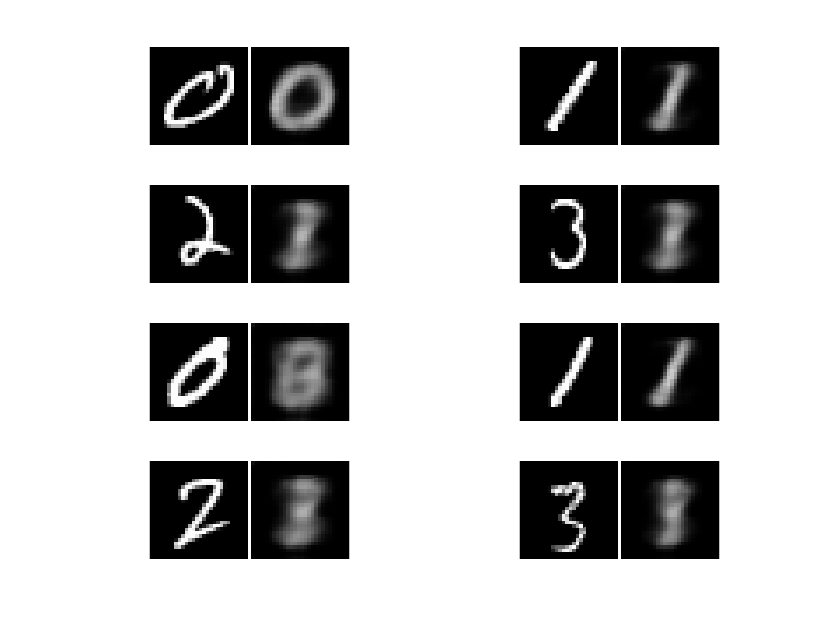

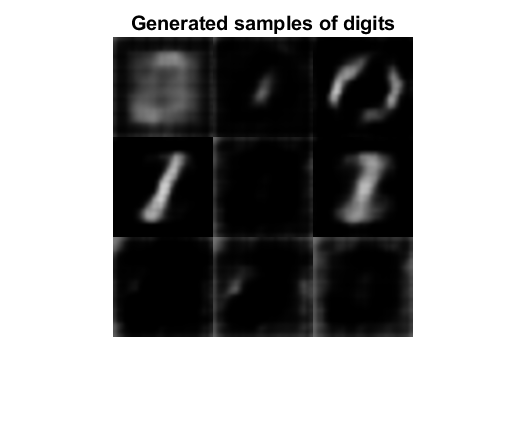


visualizeReconstruction(XTest, YTest, encoderNet8, decoderNet8)
generate(decoderNet8, latentDim)

## Test 9

fprintf("Test 9 \n")

Test 9 


[encoderNet,decoderNet, latentDim, numEpochs, lr, ~] = get_baseline_param();

momentum = 0;

[encoderNet9, decoderNet9] = run_training(numEpochs, lr, momentum, encoderNet, decoderNet, XTrain, XTest);

Epoch : 1 Test ELBO loss = 28.2304. Time taken for epoch = 93.2046s 
Epoch : 2 Test ELBO loss = 27.3135. Time taken for epoch = 93.2858s 
Epoch : 3 Test ELBO loss = 27.2297. Time taken for epoch = 94.3s 
Epoch : 4 Test ELBO loss = 27.4941. Time taken for epoch = 94.7428s 
Epoch : 5 Test ELBO loss = 27.21. Time taken for epoch = 93.2343s 
Epoch : 6 Test ELBO loss = 27.2676. Time taken for epoch = 93.3819s 
Epoch : 7 Test ELBO loss = 27.0998. Time taken for epoch = 94.3016s 
Epoch : 8 Test ELBO loss = 27.045. Time taken for epoch = 95.6346s 
Epoch : 9 Test ELBO loss = 26.811. Time taken for epoch = 97.5251s 
Epoch : 10 Test ELBO loss = 26.5354. Time taken for epoch = 99.6676s 
Epoch : 11 Test ELBO loss = 26.8358. Time taken for epoch = 102.0834s 
Epoch : 12 Test ELBO loss = 26.2846. Time taken for epoch = 103.9482s 
Epoch : 13 Test ELBO loss = 26.4495. Time taken for epoch = 106.4165s 
Epoch : 14 Test ELBO loss = 26.1908. Time taken for epoch = 107.9449s 
Epoch : 15 Test ELBO loss = 26.3

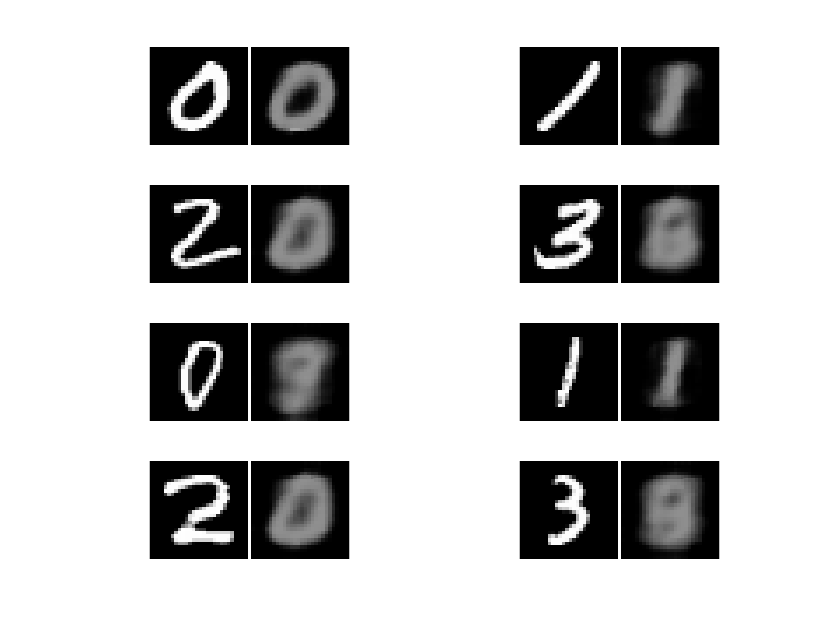

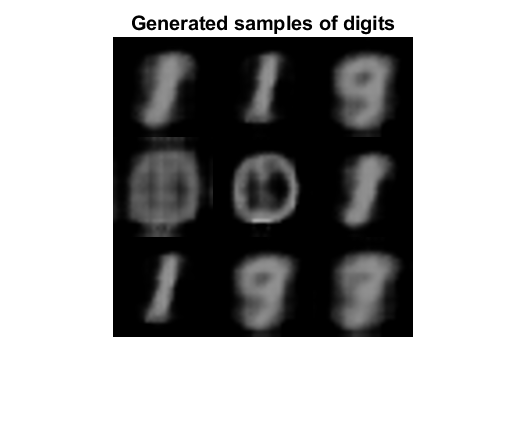


visualizeReconstruction(XTest, YTest, encoderNet9, decoderNet9)
generate(decoderNet9, latentDim)

## Test Final